**The simulations of mRNA concentrations to an abrupt drop in the mRNA production rate in cells with different total numbers of protein X or Y.**

**For Figure 5a.**

% Basic paramters
load ../Parameter_determination/Basic_parameters.mat

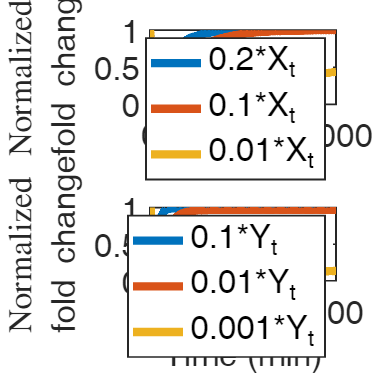

para1=para_opt;

% Symbolic solutions
load ../Solve_values/Solve_values.mat
syms_solve=[Xn_pre,Xc_pre,Xp_pre,Yn_pre,Yp_pre];



% Depletion of X
dep_fraX=[0.2,0.1,0.01];
mFC_all=zeros(1000,4);
for i=1:3
    para1(10)=para_opt(10)*dep_fraX(i);
    [kn_wt,kn_tot,y_wt,y_tot]=Xcdeplete_noFC_k0diff(para1,syms_solve);
    temp_mc=y_tot(:,2)/y_wt(2); %mc
    mFC_all(:,i)=temp_mc;
end

mFC_all_norm_X=mFC_all;
for i=1:3
    %normalization of the peaks
    temp2=min(mFC_all(:,i));
    temp3=1-temp2;
    temp4=1-(1-mFC_all(:,i))/temp3;
    mFC_all_norm_X(:,i)=temp4;
end

% Depletion of Y
dep_fraY=[0.1,0.01,0.001];
mFC_all=zeros(1000,4);
for i=1:3
    para1(11)=para_opt(11)*dep_fraY(i);
    [kn_wt,kn_tot,y_wt,y_tot]=Xcdeplete_noFC_k0diff(para1,syms_solve);
    temp_mn=y_tot(:,1)/y_wt(1); %mn
    mFC_all(:,i)=temp_mn;
end


mFC_all_norm_Y=mFC_all;
for i=1:3
    %normalization of the peaks
    temp2=min(mFC_all(:,i));
    temp3=1-temp2;
    temp4=1-(1-mFC_all(:,i))/temp3;
    mFC_all_norm_Y(:,i)=temp4;
end


% Plot
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];

fig=figure;
set(fig,'Position',[300 100 700 700]);

ax1=subplot(2,1,1);
scale_time=1:1000;
for i = 1:3
    plot(scale_time, mFC_all_norm_X(:,i), ...
        "LineWidth",5, ...
        "Color",colors(i),...
        "DisplayName",[num2str(dep_fraX(i)),'*X_t']);
    hold on
end
hold off
ax1.LabelFontSizeMultiplier=1.2;
ax1.LineWidth=1;
ax1.FontSize=20;
legend("Interpreter","tex","FontSize",20)
ylabel(['Normalized' '\newline' 'fold change'],'FontSize',20);

ax2=subplot(2,1,2);
for i = 1:3
    plot(scale_time, mFC_all_norm_Y(:,i), ...
        "LineWidth",5, ...
        "Color",colors(i),...
        "DisplayName",[num2str(dep_fraY(i)),'*Y_t']);
    hold on
end
hold off
ax2.LabelFontSizeMultiplier=1.2;
ax2.LineWidth=1;
ax2.FontSize=20;
xlim([0,200])
legend("Interpreter","tex","FontSize",20)
xlabel('Time (min)','interpreter','tex','FontSize',20);
ylabel(['Normalized' '\newline' 'fold change'],'FontSize',20);

function dydt = diffun(y,para)
%%% Differential equations of the system

%y:[mn mc Xn Xc Xp Yn Yp]
mn=y(1);
mc=y(2);
Xn=y(3);
Xc=y(4);
Xp=y(5);
Yn=y(6);
Yp=y(7);

%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]
Kv=5.8262;%fL
k0=para(1);
Kx=para(2);
Ky=para(3);
Km=para(4);
am=para(5);
ax=para(6);
ay=para(7);
bm=para(8);
bx=para(9);
%Xt=para(10);
%Yt=para(11);


dydt = zeros(7,1);
%dydt:[dmndt dmcdt dXndt dXcdt dXpdt dYndt dYpdt]

Vn=2.8;%fL
Vc=37.2;%fL

kn=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);

dydt(1)=kn-am*(Yn/Vn)*mn;
dydt(2)=am*(Yn/Vn)*mn-bm*(Xc/Vc)*mc;
dydt(3)=kn-ax*Xn;
dydt(4)=ax*Xn-bx*Xc;
dydt(5)=bx*Xc-kn;
dydt(6)=kn-ay*Yn;
dydt(7)=ay*Yn-kn;

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




function [kn_wt,kn_tot,y_wt,y_tot]=Xcdeplete_noFC_k0diff(para0,syms_solve)
%%% The function calculating the values of molecules.
%%% Reduce k0 to perturb kn


%Numerically solve the values of molecules in WT cells
syms k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv
para_sym=[k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv];
para_num=[para0,2.8,37.2,5.8262];
%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]
temp1=double(subs(syms_solve,para_sym,para_num));% Xn Xc Xp Yn Yp
temp1=temp1(~any(temp1<0,2),:);
temp2=[2.8*para0(7)/para0(5),37.2*para0(9)/para0(8)];% mn mc

y_wt=[temp2,temp1];


%paramters
Kv=5.8262;%fL
k0=para0(1);
Kx=para0(2);
Ky=para0(3);
Km=para0(4);
%am=para0(5);
%ax=para0(6);
%ay=para0(7);
%bm=para0(8);
%bx=para0(9);
%Xt=para0(10);
%Yt=para0(11);
mn=y_wt(1);
%mc=y_wt(2);
%Xn=y_wt(3);
%Xc=y_wt(4);
Xp=y_wt(5);
%Yn=y_wt(6);
Yp=y_wt(7);
Vn=2.8;%fL
%Vc=37.2;%fL

kn_wt=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);

%perturb transcription
y_ini=y_wt;
para1=para0;
para1(1)=para0(1)*0.5;

%Calculate the values of molecules after depletion
tspan=[1:1:1000];
[~,y_tot]=ode15s(@(t,y)diffun(y,para1),tspan,y_ini);

%Calculate the kn after perturbation
kn_tot=zeros(1,length(tspan));
for i=1:length(tspan)
    mn=y_tot(i,1);
    %mc=y_tot(i,2);
    %Xn=y_tot(i,3);
    %Xc=y_tot(i,4);
    Xp=y_tot(i,5);
    %Yn=y_tot(i,6);
    Yp=y_tot(i,7);
    kn_tot(i)=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);
end



end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%